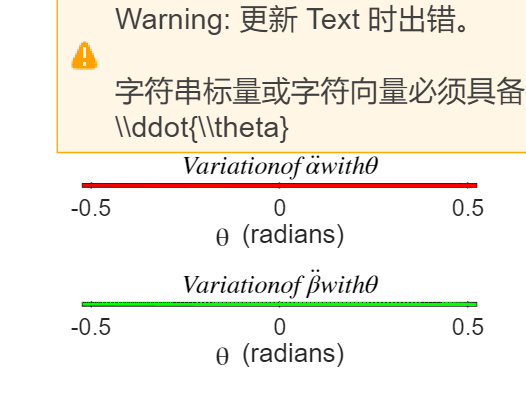

Model_consts=containers.Map; 
Model_consts('r')=0.1;
Model_consts('l0')=0.1;
Model_consts('l1')=0.8;
Model_consts('l2')=0.7;
Model_consts('m0')=15;
Model_consts('m1')=35;
Model_consts('m2')=20;
Model_consts('g')=9.81;
Model_consts('dt')=0.01;

% Define symbolic variables using sym
    theta = sym('theta');
    alpha = sym('alpha');
    beta = sym('beta');
    dtheta = sym('dtheta');
    dalpha = sym('dalpha');
    dbeta = sym('dbeta');
    ddot_theta = sym('ddot_theta');
    ddot_alpha = sym('ddot_alpha');
    ddot_beta = sym('ddot_beta');
    
    % Define additional symbolic variables
    m0 = sym('m0');
    m1 = sym('m1');
    m2 = sym('m2');
    l0 = sym('l0');
    l1 = sym('l1');
    l2 = sym('l2');
    r = sym('r');
    g = sym('g');
    tau1 = sym('tau1');
    tau2 = sym('tau2');
    
    init_stateV=init(Model_consts);
    % Define positions and their second derivatives
    
    x0 = -sin(theta)*r + theta*cos(theta)*r-cos(theta)*l0;
    y0 = cos(theta)*r + theta*sin(theta)*r-sin(theta)*l0;
    x1 = x0 - sin(alpha)*l1;
    y1 = y0 + cos(alpha)*l1;
    x2 = x1 - sin(beta)*l2;
    y2 = y1 + cos(beta)*l2;
    
    % Calculate second derivatives
    
    
    
    %ddot_x0 = -cos(theta)*ddot_theta*r - 2*sin(theta)*(diff(theta)^2)*r + theta*(-sin(theta)*ddot_theta*r + cos(theta)*ddot_theta*r);
    %ddot_y0 = -sin(theta)*ddot_theta*r + 2*cos(theta)*(diff(theta)^2)*r + theta*(cos(theta)*ddot_theta*r - sin(theta)*ddot_theta*r);
    %ddot_x0 = -cos(theta)*ddot_theta*r - (sin(theta)*diff(theta)^2 + cos(theta)*ddot_theta)*r + (ddot_theta*cos(theta) - theta*ddot_theta*sin(theta) - theta*diff(theta)^2*sin(theta))*r;
    %ddot_y0 = -sin(theta)*ddot_theta*r - (cos(theta)*diff(theta)^2 + sin(theta)*ddot_theta)*r + (ddot_theta*sin(theta) + theta*ddot_theta*cos(theta) - cos(theta)*diff(theta)^2)*r - cos(theta)*ddot_theta*l0;
    dx_0=diff(x0,theta);
    ddot_x0=diff(dx_0,theta)*dtheta^2+dx_0*ddot_theta;
    dy_0=diff(y0,theta);
    ddot_y0=diff(dy_0,theta)*dtheta^2+dy_0*ddot_theta;
    
    dx_1=diff(x1,alpha);
    ddot_x1=diff(dx_1,alpha)*dalpha^2+dx_1*ddot_alpha+ddot_x0;
    dy_1=diff(y1,alpha);
    ddot_y1=diff(dy_1,alpha)*dalpha^2+dy_1*ddot_alpha+ddot_y0;
    
    dx_2=diff(x2,beta);
    ddot_x2=diff(dx_2,beta)*dbeta^2+dx_2*ddot_beta+ddot_x1;
    dy_2=diff(y2,beta);
    ddot_y2=diff(dy_2,beta)*dbeta^2+dy_2*ddot_beta+ddot_y1;
    %ddot_x1 = ddot_x0 - ddot_alpha*l1;
    %ddot_y1 = ddot_y0 + ddot_alpha*l1;
    %ddot_x2 = ddot_x1 - ddot_beta*l2;
    %ddot_y2 = ddot_y1 + ddot_beta*l2;
    
    % Define the equations
    eq1 = -ddot_x2*(cos(beta)*l2 + cos(alpha)*l1)*m2 - (ddot_y2 + g)*(sin(beta)*l2 + sin(alpha)*l1)*m2 - ddot_x1*cos(alpha)*l1*m1 - (ddot_y1 + g)*sin(alpha)*l1*m1 == tau1;
    eq2 = -ddot_x2*cos(beta)*l2*m2 - (ddot_y2 + g)*sin(beta)*l2*m2 == tau2;
    
    % Define the normal forces
    Nx = sin(theta)*tau1 / (-l0+r*theta);
    Ny = cos(theta)*tau1 / (l0-r*theta);
    
    % Define the normal force equation
    eq3 = Nx*(ddot_x0*m0 + ddot_x1*m1 + ddot_x2*m2) + Ny*((ddot_y0 + g)*m0 + (ddot_y1 + g)*m1 + (ddot_y2 + g)*m2) == Nx^2 + Ny^2;
    
    eq4= ddot_beta-ddot_alpha==6.32*(dalpha-dbeta)+10*(alpha-init_stateV(2)-beta+init_stateV(3));
    

State_variables=init(Model_consts); %theta,alpha,beta,dtheta,dalpha,dbeta
unit_torque=1;
    % Solve the equations
    


    [ddot_theta_sol, ddot_alpha_sol, ddot_beta_sol,tau_2_sol] = solve([eq1, eq2, eq3,eq4], [ddot_theta, ddot_alpha, ddot_beta,tau2]);
    
    Controls_u(1)=Model_consts('g')*(Model_consts('m0')+Model_consts('m1')+Model_consts('m2'))*(Model_consts('l0')+Model_consts('r')*(-State_variables(1)))*cos(State_variables(1));
    
    values = struct('l0',Model_consts('l0'),'l1',Model_consts('l1') , 'l2', ...
        Model_consts('l2'), 'm1',Model_consts('m1'), 'm2',Model_consts('m2'), ...
        'm0', Model_consts('m0'), 'r', Model_consts('r'), ...
        'tau1', Controls_u(1),  ...
        'theta', State_variables(1), 'alpha',State_variables(2) , 'beta', State_variables(3), ...
        'dtheta',State_variables(4),'dalpha',State_variables(5),'dbeta',State_variables(6), ...
        'g', Model_consts('g'));
    [ddot_theta_sol, ddot_alpha_sol, ddot_beta_sol,tau_2_sol] = solve([eq1, eq2, eq3,eq4], [ddot_theta, ddot_alpha, ddot_beta,tau2]);
balanced_tau2=double(subs(tau_2_sol, values));
    %test=[(double(subs(ddot_beta_sol,values))),(double(subs(ddot_alpha_sol,values))),(double(subs(tau_2_sol,values)))]
    
    theta_values = linspace(-pi/6, pi/6, 100); % Generate 100 points from -pi/6 to pi/6
ddot_theta_vals = zeros(size(theta_values)); % Initialize array for results
ddot_alpha_vals = zeros(size(theta_values)); % Initialize array for results
ddot_beta_vals = zeros(size(theta_values)); % Initialize array for results


for i = 1:length(theta_values)
    State_variables(1)=theta_values(i);
    Controls_u(1)=unit_torque+Model_consts('g')*(Model_consts('m0')+Model_consts('m1')+Model_consts('m2'))*(Model_consts('l0')+Model_consts('r')*(-State_variables(1)))*cos(State_variables(1));
    %values.theta = theta_values(i); % Update the theta value in the struct
        values = struct('l0',Model_consts('l0'),'l1',Model_consts('l1') , 'l2', ...
        Model_consts('l2'), 'm1',Model_consts('m1'), 'm2',Model_consts('m2'), ...
        'm0', Model_consts('m0'), 'r', Model_consts('r'), ...
        'tau1', Controls_u(1),  ...
        'theta', State_variables(1), 'alpha',State_variables(2) , 'beta', State_variables(3), ...
        'dtheta',State_variables(4),'dalpha',State_variables(5),'dbeta',State_variables(6), ...
        'g', Model_consts('g'));
    ddot_theta_vals(i) = double(subs(ddot_theta_sol, values)); % Evaluate function
    ddot_alpha_vals(i) = double(subs(ddot_alpha_sol, values)); % Evaluate function
    ddot_beta_vals(i) = double(subs(ddot_beta_sol, values)); % Evaluate function

    Controls_u(1)=+Model_consts('g')*(Model_consts('m0')+Model_consts('m1')+Model_consts('m2'))*(Model_consts('l0')+Model_consts('r')*(-State_variables(1)))*cos(State_variables(1));
        values = struct('l0',Model_consts('l0'),'l1',Model_consts('l1') , 'l2', ...
        Model_consts('l2'), 'm1',Model_consts('m1'), 'm2',Model_consts('m2'), ...
        'm0', Model_consts('m0'), 'r', Model_consts('r'), ...
        'tau1', Controls_u(1),  ...
        'theta', State_variables(1), 'alpha',State_variables(2) , 'beta', State_variables(3), ...
        'dtheta',State_variables(4),'dalpha',State_variables(5),'dbeta',State_variables(6), ...
        'g', Model_consts('g'));
    ddot_theta_vals(i) =(ddot_theta_vals(i)- double(subs(ddot_theta_sol, values)))/unit_torque; % Evaluate function
    ddot_alpha_vals(i) =(ddot_alpha_vals(i)- double(subs(ddot_alpha_sol, values)))/unit_torque; % Evaluate function
    ddot_beta_vals(i) =(ddot_beta_vals(i)- double(subs(ddot_beta_sol, values)))/unit_torque; % Evaluate function
end

% Plot the results
figure;

subplot(3,1,1); % First subplot for ddot_theta
plot(theta_values, ddot_theta_vals, 'b', 'LineWidth', 2);
xlabel('\theta (radians)');
ylabel('\ddot{\theta}');
title('$Variation of \ddot{\theta} with \theta$', 'Interpreter', 'latex');
grid on;

subplot(3,1,2); % Second subplot for ddot_alpha
plot(theta_values, ddot_alpha_vals, 'r', 'LineWidth', 2);
xlabel('\theta (radians)');
ylabel('\ddot{\alpha}');
title('$Variation of \ddot{\alpha} with \theta$', 'Interpreter', 'latex');
grid on;

subplot(3,1,3); % Third subplot for ddot_beta
plot(theta_values, ddot_beta_vals, 'g', 'LineWidth', 2);
xlabel('\theta (radians)');
ylabel('\ddot{\beta}');
title('$Variation of \ddot{\beta} with \theta$', 'Interpreter', 'latex');
grid on;

now for hip

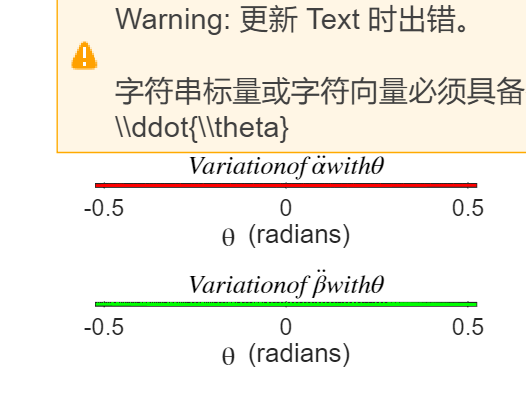

    theta_values = linspace(-pi/6, pi/6, 100); % Generate 100 points from -pi/6 to pi/6
ddot_theta_vals = zeros(size(theta_values)); % Initialize array for results
ddot_alpha_vals = zeros(size(theta_values)); % Initialize array for results
ddot_beta_vals = zeros(size(theta_values)); % Initialize array for results
[ddot_theta_sol, ddot_alpha_sol, ddot_beta_sol] = solve([eq1, eq2, eq3], [ddot_theta, ddot_alpha, ddot_beta]);

for i = 1:length(theta_values)
    State_variables(1)=theta_values(i);
    Controls_u(1)=Model_consts('g')*(Model_consts('m0')+Model_consts('m1')+Model_consts('m2'))*(Model_consts('l0')+Model_consts('r')*(-State_variables(1)))*cos(State_variables(1));
    %values.theta = theta_values(i); % Update the theta value in the struct
        values = struct('l0',Model_consts('l0'),'l1',Model_consts('l1') , 'l2', ...
        Model_consts('l2'), 'm1',Model_consts('m1'), 'm2',Model_consts('m2'), ...
        'm0', Model_consts('m0'), 'r', Model_consts('r'), ...
        'tau1', Controls_u(1),'tau2',balanced_tau2+unit_torque,  ...
        'theta', State_variables(1), 'alpha',State_variables(2) , 'beta', State_variables(3), ...
        'dtheta',State_variables(4),'dalpha',State_variables(5),'dbeta',State_variables(6), ...
        'g', Model_consts('g'));
    ddot_theta_vals(i) = double(subs(ddot_theta_sol, values)); % Evaluate function
    ddot_alpha_vals(i) = double(subs(ddot_alpha_sol, values)); % Evaluate function
    ddot_beta_vals(i) = double(subs(ddot_beta_sol, values)); % Evaluate function

    Controls_u(1)=Model_consts('g')*(Model_consts('m0')+Model_consts('m1')+Model_consts('m2'))*(Model_consts('l0')+Model_consts('r')*(-State_variables(1)))*cos(State_variables(1));
    %values.theta = theta_values(i); % Update the theta value in the struct
        values = struct('l0',Model_consts('l0'),'l1',Model_consts('l1') , 'l2', ...
        Model_consts('l2'), 'm1',Model_consts('m1'), 'm2',Model_consts('m2'), ...
        'm0', Model_consts('m0'), 'r', Model_consts('r'), ...
        'tau1', Controls_u(1),'tau2',balanced_tau2,  ...
        'theta', State_variables(1), 'alpha',State_variables(2) , 'beta', State_variables(3), ...
        'dtheta',State_variables(4),'dalpha',State_variables(5),'dbeta',State_variables(6), ...
        'g', Model_consts('g'));    ddot_theta_vals(i) =(ddot_theta_vals(i)- double(subs(ddot_theta_sol, values)))/unit_torque; % Evaluate function
    ddot_alpha_vals(i) =(ddot_alpha_vals(i)- double(subs(ddot_alpha_sol, values)))/unit_torque; % Evaluate function
    ddot_beta_vals(i) =(ddot_beta_vals(i)- double(subs(ddot_beta_sol, values)))/unit_torque; % Evaluate function
end

% Plot the results
figure;

subplot(3,1,1); % First subplot for ddot_theta
plot(theta_values, ddot_theta_vals, 'b', 'LineWidth', 2);
xlabel('\theta (radians)');
ylabel('\ddot{\theta}');
title('$Variation of \ddot{\theta} with \theta$', 'Interpreter', 'latex');
grid on;

subplot(3,1,2); % Second subplot for ddot_alpha
plot(theta_values, ddot_alpha_vals, 'r', 'LineWidth', 2);
xlabel('\theta (radians)');
ylabel('\ddot{\alpha}');
title('$Variation of \ddot{\alpha} with \theta$', 'Interpreter', 'latex');
grid on;

subplot(3,1,3); % Third subplot for ddot_beta
plot(theta_values, ddot_beta_vals, 'g', 'LineWidth', 2);
xlabel('\theta (radians)');
ylabel('\ddot{\beta}');
title('$Variation of \ddot{\beta} with \theta$', 'Interpreter', 'latex');
grid on;

varying angle beta

beta_base=State_variables(3);    
beta_values = linspace(beta_base-pi/6, beta_base+pi/6, 100); % Generate 100 points from -pi/6 to pi/6
ddot_theta_vals = zeros(size(theta_values)); % Initialize array for results
ddot_alpha_vals = zeros(size(theta_values)); % Initialize array for results
ddot_beta_vals = zeros(size(theta_values)); % Initialize array for results


for i = 1:length(theta_values)
    State_variables(3)=beta_values(i);
    Controls_u(1)=unit_torque+Model_consts('g')*(Model_consts('m0')+Model_consts('m1')+Model_consts('m2'))*(Model_consts('l0')+Model_consts('r')*(-State_variables(1)))*cos(State_variables(1));
    %values.theta = theta_values(i); % Update the theta value in the struct
        values = struct('l0',Model_consts('l0'),'l1',Model_consts('l1') , 'l2', ...
        Model_consts('l2'), 'm1',Model_consts('m1'), 'm2',Model_consts('m2'), ...
        'm0', Model_consts('m0'), 'r', Model_consts('r'), ...
        'tau1', Controls_u(1),  ...
        'theta', State_variables(1), 'alpha',State_variables(2) , 'beta', State_variables(3), ...
        'dtheta',State_variables(4),'dalpha',State_variables(5),'dbeta',State_variables(6), ...
        'g', Model_consts('g'));
    ddot_theta_vals(i) = double(subs(ddot_theta_sol, values)); % Evaluate function
    ddot_alpha_vals(i) = double(subs(ddot_alpha_sol, values)); % Evaluate function
    ddot_beta_vals(i) = double(subs(ddot_beta_sol, values)); % Evaluate function

    Controls_u(1)=+Model_consts('g')*(Model_consts('m0')+Model_consts('m1')+Model_consts('m2'))*(Model_consts('l0')+Model_consts('r')*(-State_variables(1)))*cos(State_variables(1));
        values = struct('l0',Model_consts('l0'),'l1',Model_consts('l1') , 'l2', ...
        Model_consts('l2'), 'm1',Model_consts('m1'), 'm2',Model_consts('m2'), ...
        'm0', Model_consts('m0'), 'r', Model_consts('r'), ...
        'tau1', Controls_u(1),  ...
        'theta', State_variables(1), 'alpha',State_variables(2) , 'beta', State_variables(3), ...
        'dtheta',State_variables(4),'dalpha',State_variables(5),'dbeta',State_variables(6), ...
        'g', Model_consts('g'));
    ddot_theta_vals(i) =(ddot_theta_vals(i)- double(subs(ddot_theta_sol, values)))/unit_torque; % Evaluate function
    ddot_alpha_vals(i) =(ddot_alpha_vals(i)- double(subs(ddot_alpha_sol, values)))/unit_torque; % Evaluate function
    ddot_beta_vals(i) =(ddot_beta_vals(i)- double(subs(ddot_beta_sol, values)))/unit_torque; % Evaluate function
end

错误使用 symengine
Unable to convert expression containing symbolic variables into double array. Apply 'subs'
function first to substitute values for variables.

出错 sym/double (第 868 行)
        Xstr = mupadmex('symobj::double', S.s, 0);

相关文档


% Plot the results
figure;

subplot(3,1,1); % First subplot for ddot_theta
plot(theta_values, ddot_theta_vals, 'b', 'LineWidth', 2);
xlabel('\theta (radians)');
ylabel('\ddot{\theta}');
title('$Variation of \ddot{\theta} with \theta$', 'Interpreter', 'latex');
grid on;

subplot(3,1,2); % Second subplot for ddot_alpha
plot(theta_values, ddot_alpha_vals, 'r', 'LineWidth', 2);
xlabel('\theta (radians)');
ylabel('\ddot{\alpha}');
title('$Variation of \ddot{\alpha} with \theta$', 'Interpreter', 'latex');
grid on;

subplot(3,1,3); % Third subplot for ddot_beta
plot(theta_values, ddot_beta_vals, 'g', 'LineWidth', 2);
xlabel('\theta (radians)');
ylabel('\ddot{\beta}');
title('$Variation of \ddot{\beta} with \theta$', 'Interpreter', 'latex');
grid on;